## Estimating the Rate of Change from Experimental Data

In many biological experiments, we do not know the exact equation describing a process. Instead, we collect measurements at discrete time points.

A researcher measures the number of cells in a culture every 12 hours.

Questions:

- When is the growth rate highest?

- How fast is the cell population growing at each time point?

### Let's get the data into variables

time = [0 12 24 36 48 60 72];
cells = [1200 1650 2450 3800 5600 7300 8100];

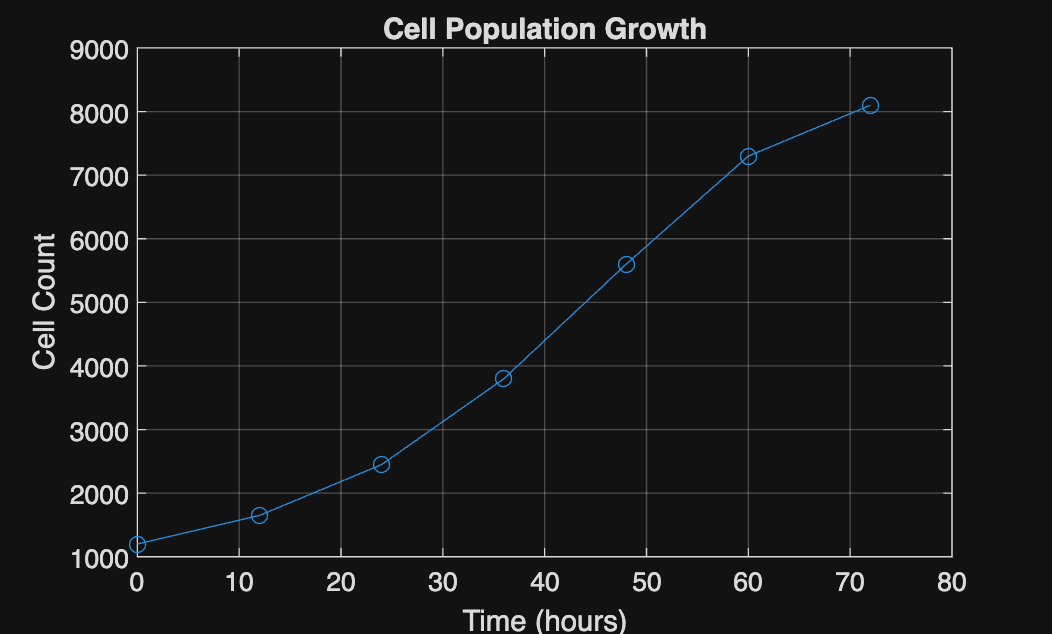

plot(time, cells, '-o')

xlabel('Time (hours)')
ylabel('Cell Count')
title('Cell Population Growth')
grid on

### But we don't have an equation to differentiate!

The `gradient` function comes to rescue.

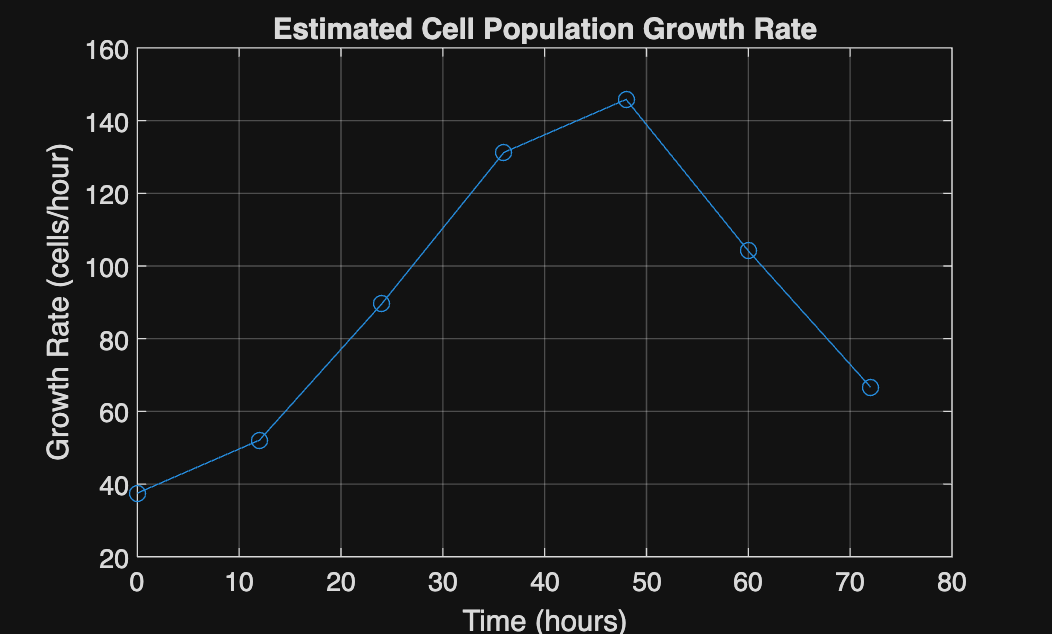

growthRate = gradient(cells, time);

plot(time, growthRate, '-o')

xlabel('Time (hours)')
ylabel('Growth Rate (cells/hour)')
title('Estimated Cell Population Growth Rate')
grid on

### What was the maximum growth rate?

[maxGrowthRate, idx] = max(growthRate);

fprintf('Maximum growth rate: %.2f cells/hour\n', maxGrowthRate);

Maximum growth rate: 145.83 cells/hour


fprintf('Observed at %.0f hours.\n', time(idx));

Observed at 48 hours.
